# RESULT: Arm Shape Comparison

*MATLAB Version: '23.2.0.2409890 (R2023b) Update 3'*

*Last revised: 8/17/2024*

*Authors: Bill Fan*

This document should contain all that is necessary for the RESULTS subsection on applying the attainability methods for comparing different overall arm shapes for reaching a specific tip pose and load configuration.

First, we will define a target task, which comprises of a target tip pose and tip load. For this example we will approximate a drawer-opening task.

%% Step 1: Define target trajectory keybpoints
% Base pose: hanging down
pose_base = [0; 0; -pi/2];
g_0 = Pose2.hat(pose_base);

% Keypoint poses: [x y theta]
pose_1 = [0.35; -0.3; 0];

poses = [pose_1];

% Create load vector
qx = 6; % Load of opening the drawer: 1N
w_tip = [qx; 0; 0]; % If we move to the left to open the drawer, then the drawer force will pull to the right

We will compare a variety of "heuristic" based shape-planning methods. Each heuristic is formulated as a cost function - for example, the observation "the best shape minimizes curvatures" associates each arm shape's cost with the sum of the curvatures.

% Step 2: 
N_nodes = 10;

shape_params = [
    45, 0, 1;
    20, 0, 1;
    4, 0, 1;
]

shape_params =     45     0     1
    20     0     1
     4     0     1



neutral_lengths = [0.5, 0.5, 0.51];

cell_cost_funcs = {
    % New shapes
    % @(mat_geom) base_curve_cost_minimum_change_in_curvature(mat_geom, [8,
    % 0, 1], 0.50), ... Really closely matched shape..?

    @(mat_geom) base_curve_cost_minimum_change_in_curvature(mat_geom, shape_params(1, :), neutral_lengths(1)), ...
    @(mat_geom) base_curve_cost_minimum_change_in_curvature(mat_geom, shape_params(2, :), neutral_lengths(2)), ...
    @(mat_geom) base_curve_cost_minimum_change_in_curvature(mat_geom, shape_params(3, :), neutral_lengths(3)), ...

    % Old shapes
    % @(mat_geom) base_curve_cost_sum_of_dists_from_target_squared(mat_geom, [20, 1], 0.51), ...
    % @(mat_geom) base_curve_cost_minimum_change_in_curvature(mat_geom, [20, 0, 1], 0.50), ...
    % @(mat_geom) base_curve_cost_sum_of_dists_from_target_squared(mat_geom, [50, 1], 0.50), ...
};
names = ["[50, 1]", "[40, 1]", "[20, 1] - min diff"];
N_shapes = length(cell_cost_funcs);

cell_segment_twists = cell(size(cell_cost_funcs));

for i_shape = 1 : numel(cell_segment_twists)
    cost_func_i = cell_cost_funcs{i_shape};
    cell_segment_twists(i_shape) = find_shape_single_seg(pose_base, poses, w_tip, N_nodes, cost_func_i);
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

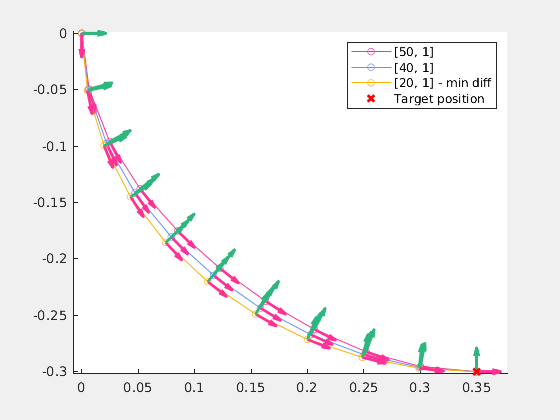


ax = axes(figure("Visible", true));
hold on;

color_green = [45 182 125] / 255;
color_yellow = [255 176 0] / 255;
color_blue = [100 143 255] / 255;
color_red = [255 48 150] / 255;

colors = [color_red; color_blue; color_yellow; color_green];

colors = [colors; colors];

for i_shape = 1 : numel(cell_segment_twists)
    segment_twists_i = cell_segment_twists{i_shape};
    poses_i = calc_poses(g_0, segment_twists_i);
    linestyle = struct("color", colors(i_shape, :), "Marker", "o", "Markersize", 5, "Displayname", names(i_shape));
    plot_poses(poses_i, ax, linestyle, true);
end
plot(poses(1, :), poses(2, :), 'rx', "MarkerSize", 7, "Linewidth", 2, "Displayname", "Target position")
legend()

We will now propose an arm design and evaluate it across these potential ways of reaching the target.

rho_outer = 0.04;
rho_inner = 0.01;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
    1, 1, 1, 1;
    0, 0, 0, 0;
    -rhos;
    ];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.51;

p_bounds = [50; 100; 100; 50];

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;
struct_design.p_bounds = p_bounds;

Now, for each arm backbone shape we will compute the reaction-requirements at each point along the arm, induced by the tip-load requirement. 

cell_q = cell(size(cell_segment_twists));
qf_all = zeros(N_nodes, N_shapes);
qm_all = zeros(N_nodes, N_shapes);

for i_shape = 1 : numel(cell_segment_twists)
    q_i = -calc_external_wrench(cell_segment_twists{i_shape}, w_tip, g_0);
    qf_all(:, i_shape) = q_i(1, :);
    qm_all(:, i_shape) = q_i(3, :);

    cell_q{i_shape} = q_i;
end

% For each target shape, compute the closest attainable shape to it.
residuals = zeros(1, N_shapes);
p_solns = zeros(4, N_shapes);
cell_closest_twists = cell(1, N_shapes);
for i = 1 : N_shapes
    %[residuals(i), p_solns(:, i)] = find_p_minimize_reaction_diff(cell_segment_twists{i}, w_tip, struct_design);
    tic
    [p_solns(:, i), ~, ~, residuals(i)] = find_p_minimize_pose_error(cell_segment_twists{i}, w_tip, struct_design, ones(1, N_nodes), p_0=[0;0;0;0]);
    toc

    cell_closest_twists{i} = solve_equilibrium_shape(N_nodes, struct_design, p_solns(:, i), w_tip);
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 62.108195 seconds.



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 55.510597 seconds.



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 72.733320 seconds.


color_green = [45 182 125] / 255;
color_yellow = [255 176 0] / 255;
color_blue = [100 143 255] / 255;
color_red = [255 48 150] / 255;
colors = [color_red; color_blue; color_green];

% Lighter colors
color_light_green = [130 205 174] / 255;
color_light_yellow = [248 203 97] / 255;
color_light_blue = [135 167 250] / 255;
color_light_red = [230 100 164] / 255;

% Darker colors
color_dark_green = [0.0706    0.5137    0.3294];
color_dark_blue = [0.2941    0.4196    0.7490];
color_dark_yellow = [0.7490    0.5176         0];
color_dark_red = [0.6549    0.1059    0.3725];
colors_dark = [color_dark_red; color_dark_blue; color_dark_green];

fig = figure("Visible", true, "Position", [0, 0, 1600, 800]);
tiledlayout(6, 4, "TileSpacing","tight", "TileIndexing", "columnmajor");
indices = 1:N_nodes;

ax = nexttile([2, 1]);
for i = 1 : N_shapes
    target_poses_i = calc_poses(g_0, cell_segment_twists{i});
    
    plot_poses(target_poses_i, ax, struct("color", colors(i, :), "markerfacecolor", colors(i, :), "linewidth", 3, "marker", "o", "markersize", 5), false);
end
 quiver(target_poses_i(1, 3, end), target_poses_i(2, 3, end), 0.01*w_tip(1), 0.01*w_tip(2), "color", color_yellow, "linewidth", 2, "MaxHeadSize", 2);

xlabel("X [m]")
ylabel("Y [m]")
grid on
fontsize(15, "points")

ax = nexttile([4, 1])

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.0833 0.1100 0.2041 0.5171]
            Units: 'normalized'

  Show all properties



col = [];
for i = 1 : numel(cell_segment_twists)
    ax = nexttile([2, 1]);
    col = [col, ax];
    target_poses_i = calc_poses(g_0, cell_segment_twists{i});
    closest_poses_i = calc_poses(g_0, cell_closest_twists{i});
    
    plot_poses(target_poses_i, ax, struct("color", colors_dark(i, :), "markerfacecolor", colors_dark(i, :), "linestyle", "-","linewidth", 2, "marker", "o", "markersize", 5), true);
    plot_poses(closest_poses_i, ax, struct("color", colors(i, :), "markerfacecolor", colors_dark(i, :), "linestyle", ":","linewidth", 2, "marker", "o", "markersize", 5), true);
    ylabel("Y [m]")
    grid on
end
xlabel("X [m]")
linkaxes(col)

%%% Row 2: attainable absolute reaction space
% Plot the absolute rxn prisms
s = linspace(0, 1, N_nodes);

N_test_ps = 100;
p_sample = diag(struct_design.p_bounds) * unifrnd(0, 1, 4, N_test_ps);
color_gray = [150,150,150]/255;
axs_row = cell(size(cell_segment_twists));
for i_shape= 1 : numel(cell_segment_twists)
    axs_row{i_shape} = nexttile([2, 1]);
    hold on

    % Get all of the boundary traces for this shape
    segment_twists_i = cell_segment_twists{i_shape};
    [bndry_af_i, bndry_am_i] = compute_attainable_wrench_space(segment_twists_i, struct_design);
    mat_s = repmat(indices, [size(bndry_af_i, 2), 1]);

    plot_style = struct("facealpha", 0.6);
    plot_wrench_hull_white_lie(bndry_af_i, bndry_am_i, axs_row{i_shape}, colors(i_shape, :), plot_style);
    plot3(qf_all(:, i_shape), qm_all(:, i_shape), mat_s', "color", color_yellow, "linewidth",3, "marker", "o", "markerfacecolor", color_yellow);
    zlabel("s [unitless]", "Rotation", 90)
    grid on
    view(110, 28);
end
xlabel("a_f [N]")
ylabel("a_m [Nm]")
linkaxes([axs_row{:}]);

% Row 3 - relative reaction traces
rltv_qf = qf_all - qf_all(1, :);
rltv_qm = qm_all - qm_all(1, :);

ax_rltv_space = [];
for i_shape = 1 : numel(cell_segment_twists)
    ax_rltv_space = [ax_rltv_space, nexttile([2, 1])];

    segment_twists_i = cell_segment_twists{i_shape};
    [bndry_af_i, bndry_am_i] = compute_attainable_wrench_space(segment_twists_i, struct_design);
    [cell_afs, cell_ams] = relative_attainable_wrench_hull(bndry_af_i, bndry_am_i);

    hold on
    for i = 1 : N_nodes
        fill(cell_afs{i}, cell_ams{i}, colors(i_shape, :), "facealpha", 0.4);
    end

    rltv_bndry_af_i = bndry_af_i - bndry_af_i(1, :);
    rltv_bndry_am_i = bndry_am_i - bndry_am_i(1, :);

    [rltv_metric_i, closest_pts] = calc_rltv_attainability_metric(rltv_qf(:, i_shape), rltv_qm(:, i_shape), rltv_bndry_af_i, rltv_bndry_am_i);
    fprintf("Relative metric: %.2f\n", sum(rltv_metric_i));

    plot(rltv_qf(:, i_shape), rltv_qm(:, i_shape), color=color_yellow, markerfacecolor=color_yellow, linewidth=1.5, marker="o", markersize=3)
    plot(closest_pts(1, :), closest_pts(2, :), color=colors_dark(i_shape, :), markerfacecolor=colors_dark(i_shape, :), linewidth=1.5, marker="o", markersize=3);
    ylabel("\Delta a_m [Nm]")
    grid on
end

Relative metric: 132.85
Relative metric: 113.51
Relative metric: 167.34


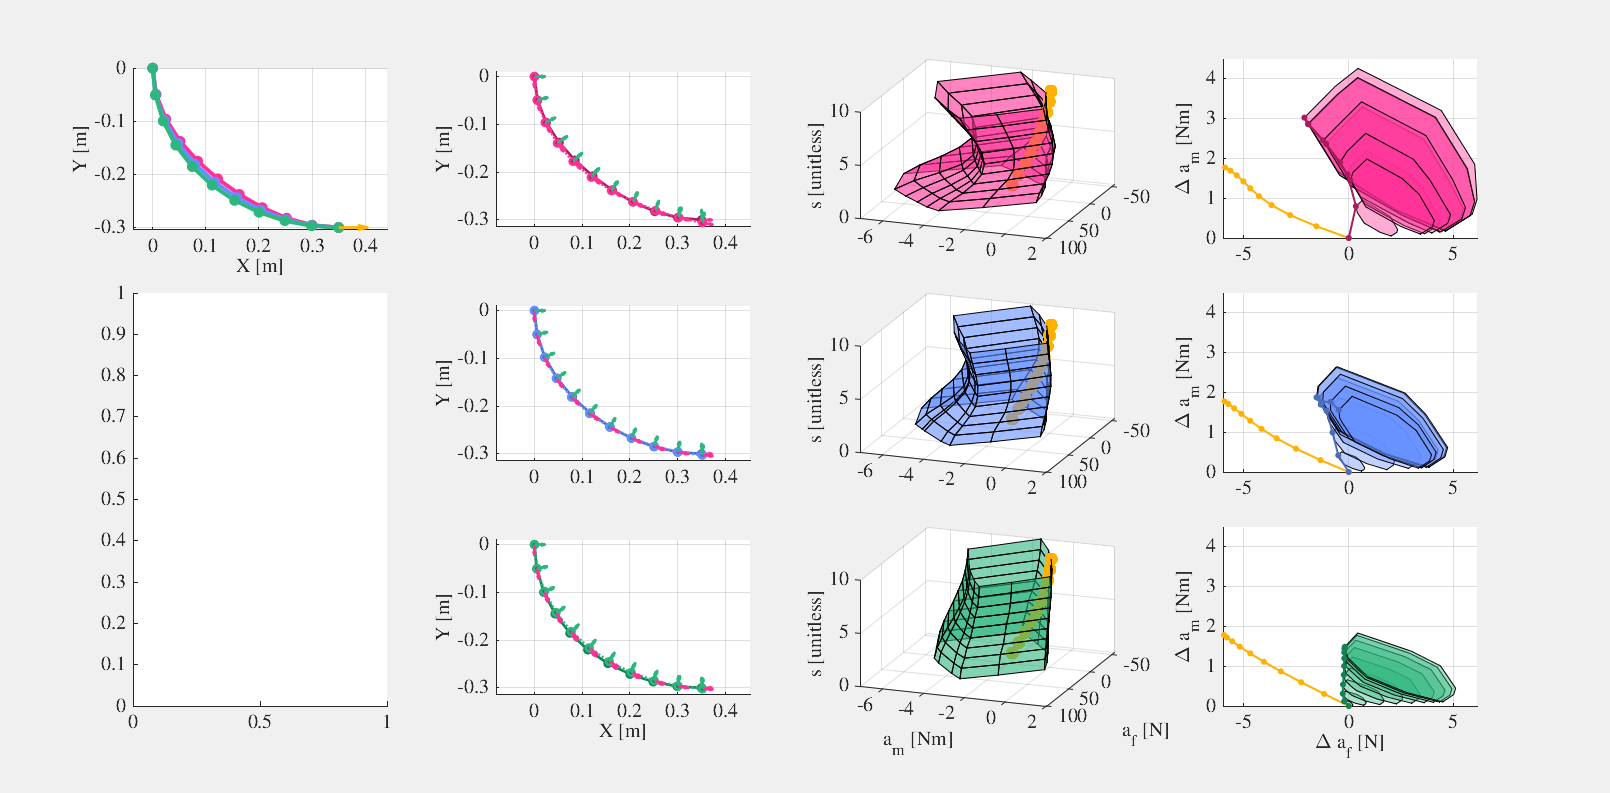

xlabel("\Delta a_f [N]")
linkaxes(ax_rltv_space);
ylim([0, 4.5]);

fontsize(15, "points")
fontname("Nimbus Roman")

% Compute results table
abs_metrics = zeros(N_shapes, 1);
rltv_metrics = zeros(N_shapes, 1);

tip_pose_errors = zeros(N_shapes, 3);
pose_errors = zeros(N_shapes, 3);

for i = 1 : N_shapes

    % Compute absolute unattainability
    abs_metric_i = calc_abs_attainability_metric(cell_segment_twists{i}, w_tip, struct_design);
    
    % Compute relative unattainability
    [bndry_af_i, bndry_am_i] = compute_attainable_wrench_space(cell_segment_twists{i}, struct_design);
    rltv_bndry_af_i = bndry_af_i - bndry_af_i(1, :);
    rltv_bndry_am_i = bndry_am_i - bndry_am_i(1, :);

    w_external = calc_external_wrench(cell_segment_twists{i}, w_tip, struct_design.g_0);
    rltv_metric_i = calc_rltv_attainability_metric(rltv_qf(:, i), rltv_qm(:, i), rltv_bndry_af_i, rltv_bndry_am_i);

    fprintf("Shape %d - abs un-attainability: %.2f | rltv un-attainability: %.2f \n", i, abs_metric_i, sum(rltv_metric_i));  

    % Compute poses, add tip pose to table      
    target_poses_i = calc_poses(g_0, cell_segment_twists{i});
    closest_poses_i = calc_poses(g_0, cell_closest_twists{i});
    tip_pose_errors(i, :) = Pose2.vee(target_poses_i(:, :, end) * inv(closest_poses_i(:, :, end)))';
    
    % Compute total pose error
    for i_pose = 1 : N_nodes
        error_i = Pose2.vee(target_poses_i(:, :, i_pose + 1) * inv(closest_poses_i(:, :, i_pose+1)));
        pose_errors(i, :) = pose_errors(i) + error_i; 
    end

    abs_metrics(i) = abs_metric_i;
    rltv_metrics(i) = sum(rltv_metric_i);
    
end

Shape 1 - abs un-attainability: 0.23 | rltv un-attainability: 132.85 
Shape 2 - abs un-attainability: 0.10 | rltv un-attainability: 113.51 
Shape 3 - abs un-attainability: 0.00 | rltv un-attainability: 167.34 


pressures = p_solns';
tip_pose_errors = [tip_pose_errors, vecnorm(tip_pose_errors, 2, 2)];
pose_errors = [pose_errors, vecnorm(pose_errors, 2, 2)];
tab = table(abs_metrics, rltv_metrics, pressures, tip_pose_errors, pose_errors);
tab.Properties.VariableNames = ["Abs. Unattainablty", "Rltv. Unattainability", "Actuator Pressures [kPa]", "Tip pose errors(X, Y, theta, norm) [m, m, rads]", "Total pose error along arm (X, Y, theta, norm) [m, m, rads]"];
tab

tab = 3×5 table
    Abs. Unattainablty    Rltv. Unattainability           Actuator Pressures [kPa]            Tip pose errors(X, Y, theta, norm) [m, m, rads]     Total pose error along arm (X, Y, theta, norm) [m, m, rads]
    __________________    _____________________    _______________________________________    ________________________________________________    ___________________________________________________________

            0.2343               132.85            19.753     49.624     67.524     3.6886    -0.051069    -0.062084      0.18028       0.1974         -0.034434     -0.04545      0.19692      0.20501      
          0.096293               113.51            40.578     68.177     97.719     1.4416    -0.024508    -0.026069     0.079167     0.086877         -0.019846    -0.021407     0.083829     0.08

### Test: finding shape via attainability

error("The following will take 5 minutes to run")

The following will take 5 minutes to run

f_attnblty_cost = @(mat_geom) (...
    calc_abs_attainability_metric([mat_geom_to_g_circ(mat_geom)], w_tip, struct_design) + ...
    0.1 * base_curve_cost_minimum_change_in_curvature(mat_geom, [20, 0, 1], 0.50)...
);

tic
opts = optimoptions("fmincon", "MaxFunctionEvaluations", 3e3, "Display", "iter", "algorithm", "interior-point");
initial_guess = [cell_segment_twists{1}(1, :); cell_segment_twists{1}(3, :)];
initial_guess = initial_guess(:);
[shape_soln, res] = find_shape_single_seg(pose_base, pose_1, w_tip, N_nodes, f_attnblty_cost, opts, initial_guess)
toc

function cost = base_curve_cost_sum_of_dists_from_target_squared(mat_geom, w, target_l)
    all_twists = [mat_geom_to_g_circ(mat_geom)];
    all_ls = all_twists(1, :);
    all_curvatures = all_twists(3, :);

    dist_from_target_l = all_ls - target_l;
    indiv_costs = [norm(dist_from_target_l); norm(all_curvatures)];
    cost = dot(w, indiv_costs);
end

function cost = base_curve_cost_minimum_change_in_curvature(mat_geom, w, target_l)
    all_twists = [mat_geom_to_g_circ(mat_geom)];
    all_ls = all_twists(1, :);
    all_curvatures = all_twists(3, :);

    dist_from_target_l = all_ls - target_l;
    indiv_costs = [norm(dist_from_target_l); norm(all_curvatures); norm(diff(all_curvatures))];
    cost = dot(w, indiv_costs);
end


function [boundary_af, boundary_qf] = compute_attainable_wrench_space(mat_segment_twists, struct_design)
    boundary_ps = sample_edges_of_cuboid(3, struct_design.p_bounds);
    
    [boundary_af, boundary_qf] = compute_reaction_traces(boundary_ps, mat_segment_twists, struct_design);
end

function [cell_rltv_bndry_af_per_node, cell_rltv_bndry_am_per_node] = relative_attainable_wrench_hull(bndry_af, bndry_am)
    N_nodes = size(bndry_af, 1);

    cell_rltv_bndry_af_per_node = cell(1, N_nodes);
    cell_rltv_bndry_am_per_node = cell(1, N_nodes);

    cell_rltv_bndry_af_per_node{1} = [0, 0];
    cell_rltv_bndry_am_per_node{1} = [0, 0];

    % Compute all the relative attainble reaction traces
    % These points will form the boundary of the relatively attainable
    % reaction space for each node. 
    rltv_bndry_af = bndry_af - bndry_af(1, :);
    rltv_bndry_am = bndry_am - bndry_am(1, :);

    for i = 2 : N_nodes
        % Order the points for each node, and only keep the ones that
        % contribute to the convex hull
        i_bndry = boundary(rltv_bndry_af(i, :)', rltv_bndry_am(i, :)', 0);

        cell_rltv_bndry_af_per_node{i} = rltv_bndry_af(i, i_bndry);
        cell_rltv_bndry_am_per_node{i} = rltv_bndry_am(i, i_bndry);
    end
end